Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" (https://www.crcpress.com/9781138589940)

# Integrating the Sacherer equations (Section 12.1)

Volker Ziemann, 211113, CC-BY-SA-4.0

The dynamics of the beam size of a beam with emittances $\varepsilon_x$ and $\varepsilon_y$ in the presence of space-charge can be described by Equations 12.4, often attributed to Sacherer. Here we convert these two second-order differential equations to four first-order equations and use ode45() to numerically integrate the beamsizes $\sigma_x$ and $\sigma_y$ through ten FODO cells with a $60^o$ phase advance per cell in both planes.

In this example we first define the emittaces `epsx`  and `epsy,` as well as the perveance `Kperv` for a 25 MeV proton beam with a current of 10 mA. For simplicity, we make these variables available as `global` to the called functions. Here we also define the initial Twiss parameters, which are those of a zero-current $60^o$ FODO lattice.

clear all; close all
global epsx epsy Kperv             % needed in sachfun.m
epsx=1e-6; epsy=1e-6; Kperv=5e-8;  % parameters 
betax=10.19292; alphax=-1.238978;  % initial values
betay=10.19292; alphay=1.238978;

Then we assign the initial valuesx0() for the integration. Note that $x_0(2)=dx_0(1)/ds$ and likewise $x_0(4)=dx_0(3)/ds$.

x0=zeros(4,1);                     % initial sigmas
x0(1)=sqrt(epsx*betax);            % sigmax
x0(2)=-alphax*sqrt(epsx/betax);    % sigmax'
x0(3)=sqrt(epsy*betay);            % sigmay
x0(4)=-alphay*sqrt(epsy/betay);    % sigmay'

Now we call the built-in integration routine `ode45()` with the right-hand side of the differential equation encoded in the function `sachfun(),` defined below,  and initial values `x0`.  Note also that we specify a small stepsize, which is necessary to catch the transitions from no-field outside to full field inside the quadrupoles. 

[s,x]=ode45(@sachfun,[0,100],x0,odeset('MaxStep',1e-2));

Once ode45() completes the values of `x=`( $\sigma_x ,\sigma'_x, \sigma_y,$ and $\sigma'_y$) at position s are available. We immediately use them to plot $\sigma_x$ and $\sigma_y$ along our ten FODO cells.

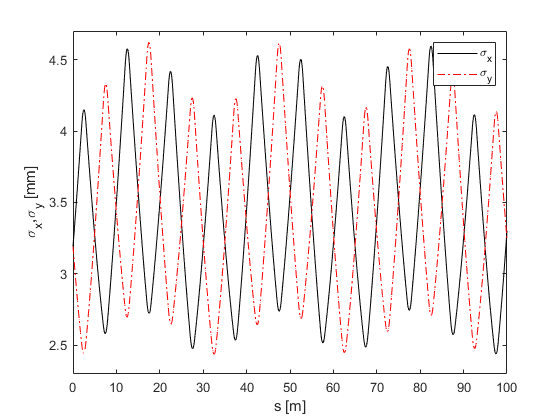

plot(s,1e3*x(:,1),'k',s,1e3*x(:,3),'r-.')
ylim([2.3,4.7])
xlabel('s [m]'); ylabel('\sigma_x,\sigma_y [mm]')
legend('\sigma_x','\sigma_y')

And now it's time to explore different currents, encode by the value of $K$ or different emittances.

## Appendix

The function `sachfun()` returns the right-hand side of the two second-order ordinary differential equations from Equation 12.4, converted to a system of four first-order differential equations. Here we use the variables `x(1)=sigx`, `x(2)=sigx'`, `x(3)=sigy`, and `x(4)=sigy'.` The input of `sachfun()` are the position s and the vector x(). Moreover, the focusing from the quadrupoles is encapsulated in the function `k1()`, defined below.  Note that the emittances $\varepsilon_x$ and $\varepsilon_y$, as well as the perveance $K$are passed to the function as globals.

function dxds=sachfun(s,x)
global epsx epsy Kperv
dxds=zeros(4,1);
dxds(1)=x(2);
dxds(2)=-k1(s).*x(1)+epsx^2./x(1).^3+Kperv./(x(1)+x(3));
dxds(3)=x(4);
dxds(4)=k1(s).*x(3)+epsy^2./x(3).^3+Kperv./(x(1)+x(3));
end

The focusing strength at position s in a 60-degree FODO lattice is returned by the following function `k1()`.  

% lattice focusing function
function out=k1(s)
kk1=0.29979*0.716792;  % quadrupole strength for 60-degree FODO
out=zeros(length(s),1);
out(mod(s,10)>=2 & mod(s,10)<=3)=kk1;
out(mod(s,10)>=7 & mod(s,10)<=8)=-kk1;
end